# **Signal and System CA3**

## **Part 3.**

- First we receive the input images.

path = './data/';
file = 'pcb.jpg';
source = [path, file];
PCB = imread(source);
file = 'ic.png';
source = [path, file];  
IC = imread(source);

- We should make a upside down version of IC imaged using builtin function `imrotate`.

rotated_IC = imrotate(IC, 180);

- Then convert the images to gray for doing corrolation.

gray_IC = rgb2gray(IC);
gray_PCB = rgb2gray(PCB);
gray_rotated_IC = rgb2gray(rotated_IC);

- Now we use `corr_matrix `function to calculate corrolation of the IC and PCB.

- This function gets gray format of the IC and PCB and convert the IC to double precision for better calculation.

- Now we have to normalize `gray_IC`.  So we calculate the average of `gray_IC` and subtracts this average from `gray_IC` itself.

- Now we can start finding the ICs. We iterate through the 2d matrix of the PCB and in each iteration, we crop a segment, equal to size of the IC. Then we normalize this cropped segment with same technique in the previous part.

- Now we can calculate the corrolation of the cropped part and IC itself using `corr_coef` function. This function implements the formula provided in the project description. Then store this calculated corrolation and store it in `corr_result`.

- We do this for both the IC image and its rotated version.


$$
\text{Correlation Coeff}(x,y) = \frac{\sum_{n=1}^{L} x[n]y[n]}{(\sqrt{\sum_{n=1}^{L} x^2[n]) \times (\sum_{k=1}^{L} y^2[k]})}}
$$


normal_res = corr_images(gray_IC , gray_PCB);
rotated_res = corr_images(gray_rotated_IC , gray_PCB);

- Now we merge the results in `result` variable for simpler handling of both version's result. 

result = {normal_res ; rotated_res};

- We can draw the blue boxes around each found IC in the image using `draw_boxes` function. This function gets the PCB and IC images and the results of corrolation. This function sets a threshold and only if the calculated corrolation is bigger than this threshold, it is considred as an found IC.

- This threshold is found practical and we didn't use any percise method to calculate it.

- After this, we use the location of the corrolated result to draw the blue rectangles on the PCB image and also return it.

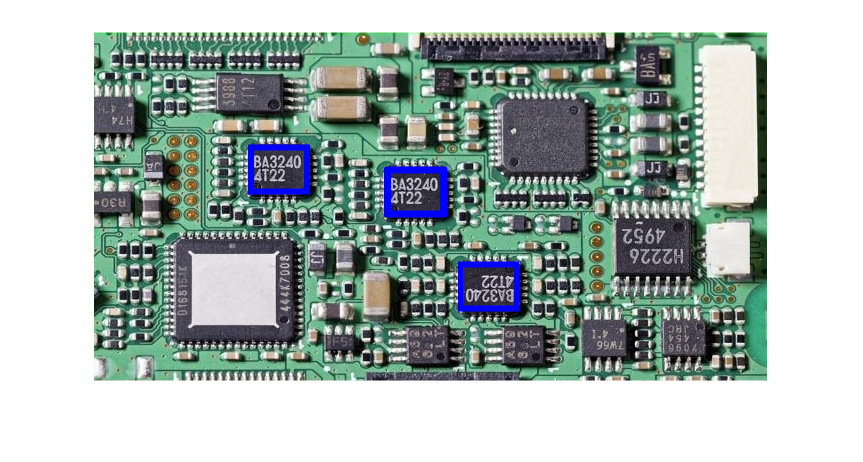

final_image = draw_boxes(PCB, gray_IC, result);

- In the end we show all the images and and the answer.

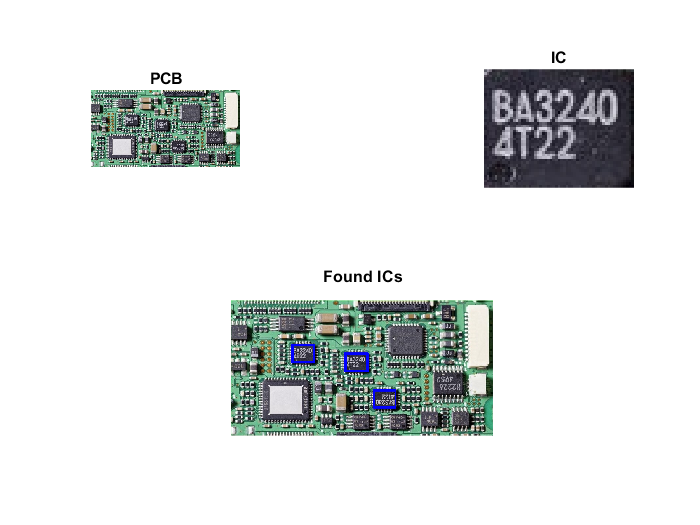

figure(); 
subplot(2, 3, 1), imshow(PCB), title('PCB');
subplot(2, 3, 3), imshow(IC), title('IC');
subplot(2, 3, [4,5,6]), imshow(final_image), title('Found ICs');

function corr_coef = corr_2d(x, y)
   corr_coef = sum(x.*y, 'all') / sqrt(sum(x.*x, 'all') * sum(y.*y, 'all'));
end

function output = my_normalize(image, width, height)
    output = image -(sum(image , 'all')/(width * height));
end

function corr_result  = corr_images(gray_IC , gray_PCB)
  [IC_width , IC_height] = size(gray_IC);   
  [PCB_width , PCB_height] = size(gray_PCB);
  gray_IC = double(gray_IC);
  corr_result = zeros(PCB_width-IC_width+1 , PCB_height-IC_height+1);
  normal_gray_IC = my_normalize(gray_IC, IC_width, IC_height);
  for i = 1 : PCB_width - IC_width + 1 
      for j = 1 : PCB_height- IC_height + 1
         cropped_PCB =  double(gray_PCB(i:i+IC_width-1 , j:j+IC_height-1)); 
         normal_cropped = my_normalize(cropped_PCB, IC_width, IC_height);
         corr_calc = corr_2d(normal_cropped , normal_gray_IC);
         corr_result(i , j) = corr_calc;
      end
  end
end

function final_image = draw_boxes(PCB, IC, result)
  threshold = 0.65;  
  [IC_width, IC_height] = size(IC);
  figure();
  imshow(PCB);
  hold on;
  for l = 1:length(result)
      [row , col] = find(result{l , 1} > threshold);
       for k = 1 : length(row)
         rectangle('Position', [col(k) row(k) IC_height-1  IC_width-1] , 'Edgecolor' , 'b' , 'LineWidth',3);
       end   
  end
  final_image = frame2im(getframe(gcf));
end